% Дано
N = 9; % Ваш вариант
V1 = 1; % Посчитано по Шарапову, а можно взять из воздуха в диапазоне от 1 до 2 В
E = 100; % Взято из воздуха
Rc = 100 + 20 * N;
Uout = 10 + 2 * N;
Rn = 300 + 30 * N + 20;
fn = 0.5 + 0.2 * N;
fv = 200 * 1e3; % >= 200 
Given = table(N, V1, E, Rc, Rn, Uout, fn, fv, 'VariableNames', ...
    ["N", "V1 [В]","E [В]", "Rс [Ом]", "Rн [Ом]", "Uвых [В]", "fн [Гц]", "fв [Гц]"]);
display(Given)
% 1) Выбор положения рабочей точки транзистора
    Imin = 1e-3; % Всегда одно и то же (а мб смотрится по хар-кам транзистора)
    Umin = 1; % Всегда одно и то же (а мб смотрится по хар-кам транзистора)
    dUke = 2; % Всегда одно и то же
    U0 = Umin + Uout + dUke;
    Ue = 0.2 * E;
    Rk = (E - Ue - U0 - Uout) / (Imin + Uout / Rn);
    I0 = Imin + Uout/ Rk + Uout / Rn;
    P0 = I0 * U0;
    Table_1 = table(Imin * 1e3, Umin, dUke, U0, Ue, Rk, I0 * 1e3, P0, 'VariableNames', ...
        ["Imin [мА]", "Umin [В]", "dUкэ [В]", "U0 [В]", "Uэ [В]", "Rк [Ом]", "I0 [мА]", "P0 [Вт]"]);
    display(Table_1)
% 2) Расчет элементов цепи смещения по постоянному току 
    Re = Ue / I0;
    beta = 100; % Смотрится по хар-кам транзистора % ВБИТЬ
    Ib = I0 / beta;
    Rb = 1500; % Берется из воздуха в диапазоне 1-2 кОм или считается по Шарапову
    Ube = 0.7; % У кремниевых транзисторов всегда 0.7
    R1 = E * Rb / (Ue + Ube + Rb * Ib);
    R2 = R1 * Rb / (R1 - Rb);
    Table_2 = table(Re, beta, Ib * 1e3, Rb * 1e-3, Ube, R1 * 1e-3, R2 * 1e-3, 'VariableNames', ...
        ["Rэ [Ом]", "beta [безразм]", "Iб [мА]", "Rб [кОм]", " [В]", "R1 [кОм]", "R2 [кОм]"]);
    display(Table_2)
% 4) Расчет величин емкостей конденсаторов
    h11e = 50 + 26 / (I0 * 1e3) * (1 + beta); % цифры 50 и 26 всегда одни и те же
    Rin = Rb * h11e / (Rb + h11e);
    C = 57 / (2 * pi * fn) * 1e3;
    % цифры 10, 10 и 25 взяты по шарапову
    C1 = C * 1 / (10 * (Rc * 1e-3 + Rin * 1e-3));
    C2 = C * 1 / (10 * (Rn * 1e-3 + Rk * 1e-3));
    C3 = C * (1 + beta) * 1 / (25 * (Rc * 1e-3 * Rb * 1e-3 / (Rc * 1e-3 + Rb * 1e-3) + h11e * 1e-3));
    Table_3 = table(h11e, Rin, C1, C2, C3, 'VariableNames', ...
        ["h11э [Ом]", "Rвх [Ом]", "С1 [мкФ]", "С2 [мкФ]", "С3 [мкФ]"]);
    display(Table_3)
% 4) График зависимости коэфициента гармоник от уровня выходного сигнала
    x = [29.8 29.7 29.65 29.618 29.615 29.56 29.29 29.11 29.01 29.0 28.95]; % у всех получатся разные значения
    y = [6.49 6.17 5.9 5.67 5.48 5.34 5.23 5.15 5.09 5.06 5.03]; % у всех получатся разные значения

x =    26.8000   26.7000   26.6500   26.6180   26.6150   26.5600   26.2900   26.1100   26.0100   26.0000   25.9500


y =     3.4900    3.1700    2.9000    2.6700    2.4800    2.3400    2.2300    2.1500    2.0900    2.0600    2.0300


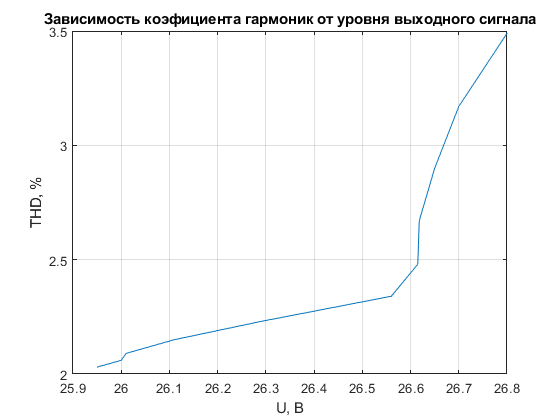

    plot(x, y)
    grid on
    xlabel("U, В")
    ylabel("THD, %")
    title("Зависимость коэфициента гармоник от уровня выходного сигнала")
    saveas(gca, "Plot2.jpg"); % У всех свой путь куда сохранять картинку